% function prof = MissionProfile(F_H, Takeoff_speed)
% Setup 
clc;
clear;
close all; 


i = 1 % motorcombo

i = 1

j = 1 % battery combo

j = 1

k = 25 % payload

k = 25


 D = James_MotorCombo(i); 
 B = BatteryInfo(j); 

 
 Bat_Remain_mAh = str2double(B.Battery_Cap_mAH)

Bat_Remain_mAh = 22000

 
[P, WeightForce] = motorbat_thrustcheck(i,j,k); 


% Takeoff ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

F_Height = 100; % meters  --- Cruising Altitude

Takeoff_s = 20; % kmh --- Takeoff Speed
Takeoff_s = Takeoff_s*1000/3600; % m/s conversion

Takeoff_As = 3; % ft^2 --- Takeoff Surface Area
Takeoff_As = Takeoff_As*0.092903; % m^2

P_row = 1.205; % kg/m^2 -- Air density
C_d = 1.2; % Coefficient of Drag *double check* 

Takeoff_Drag = 0.5*P_row*(Takeoff_s^2)*C_d*Takeoff_As  

Takeoff_Drag = 6.2193


Takeoff_Est_t = F_Height/Takeoff_s % in seconds

Takeoff_Est_t = 18

Takeoff_Total_DF = WeightForce + Takeoff_Drag 

Takeoff_Total_DF = 186.1803

[thrust_indx, thrust_N] = ThrustGivenF_WIP(D, Takeoff_Total_DF) 

thrust_indx = 5

thrust_N = 24.2307

Takeoff_thrust_total_estimate = thrust_N*8; 


figure(1)
view([90 0])
hold on
p = plot3(0, 50, 0, 'o')

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0
              YData: 50
              ZData: 0

  Show all properties


set(p, 'linewidth', 10)
mArrow3([0,50,0], [0, 50, 0-WeightForce-Takeoff_Drag], 'facealpha', 0.3, 'color', 'red','stemWidth', 2)

ans =   Patch with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.3000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [302×251 double]
     Vertices: [354×3 double]

  Show all properties


mArrow3([0,50,0], [0, 50, 0+Takeoff_thrust_total_estimate ], 'facealpha', 0.3, 'color', 'blue','stemWidth', 2)

ans =   Patch with properties:

    FaceColor: [0 0 1]
    FaceAlpha: 0.3000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [302×251 double]
     Vertices: [354×3 double]

  Show all properties


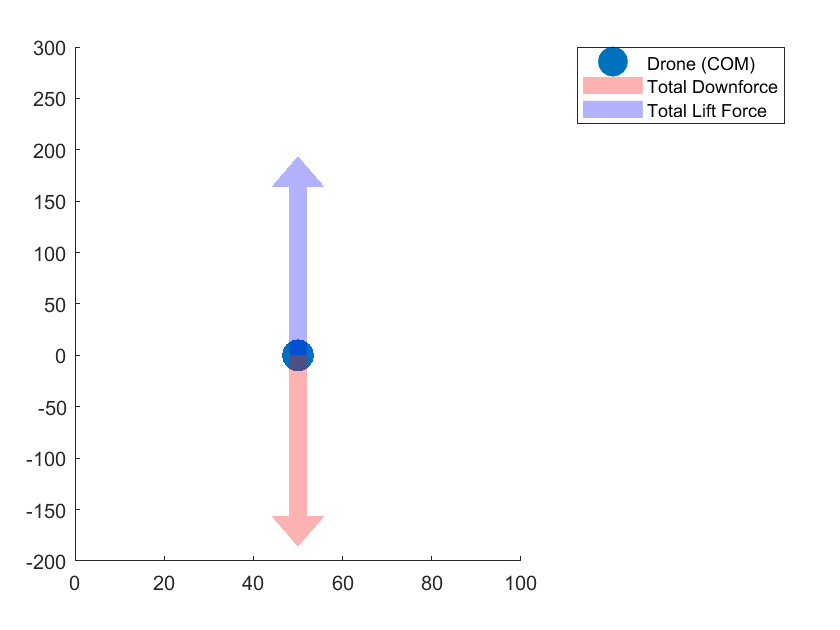

xlim([0 100])
ylim([0 100])
zlim([-200 300])
legend("Drone (COM)", "Total Downforce", "Total Lift Force")


Battery_Cap_Discharge = 0.8; 
Takeoff_Current_Draw = 8*D.Current_A(thrust_indx, 2)

Takeoff_Current_Draw = 104

Takeoff_Capacity_Usage_mAh = (((Takeoff_Est_t/3600)*Takeoff_Current_Draw)/Battery_Cap_Discharge)*1000 % mAh

Takeoff_Capacity_Usage_mAh = 650


Bat_Remain_mAh = Bat_Remain_mAh - Takeoff_Capacity_Usage_mAh

Bat_Remain_mAh = 21350


% Flight 

Distance = 4; % miles  --- Total Distance required for travel
Distance = Distance*1609.34;  % miles --> meters

Cruising_s = 40; % kmh --- Cruising Speed
Cruising_s = Cruising_s*1000/3600; % m/s conversion

Cruising_As = 2; % ft^2 --- Takeoff Surface Area
Cruising_As = Cruising_As*0.092903; % m^2

P_row = 1.205; % kg/m^2 -- Air density
C_d = 1.2; % Coefficient of Drag *double check* 

Cruising_Drag = 0.5*P_row*(Cruising_s^2)*C_d*Cruising_As  

Cruising_Drag = 16.5849

syms Ft t1; 
eqn1 = Ft*cosd(t1) == WeightForce;
eqn2 = Ft*sind(t1) == Cruising_Drag;
S = solve([eqn1, eqn2], [Ft,t1], "Real",true)

S = struct with fields:
    Ft: [2×1 sym]
    t1: [2×1 sym]


Thrust_Est_Cruise = double(S.Ft(1,1)); 
Angle_Est_Cruise = double(S.t1(1,1));



Cruising_Est_t = (Distance/Cruising_s)/60 % in minutes

Cruising_Est_t = 9.6560


[thrust_indx2, thrust_N2] = ThrustGivenF_WIP(D, Thrust_Est_Cruise) 

thrust_indx2 = 5

thrust_N2 = 24.2307



Takeoff_Flight_Draw = 8*D.Current_A(thrust_indx2, 2)

Takeoff_Flight_Draw = 104

Takeoff_Capacity_Usage_mAh = (((Cruising_Est_t/60)*Takeoff_Flight_Draw)/Battery_Cap_Discharge)*1000 % mAh

Takeoff_Capacity_Usage_mAh = 2.0921e+04


Bat_Remain_mAh = Bat_Remain_mAh - Takeoff_Capacity_Usage_mAh

Bat_Remain_mAh = 428.5800